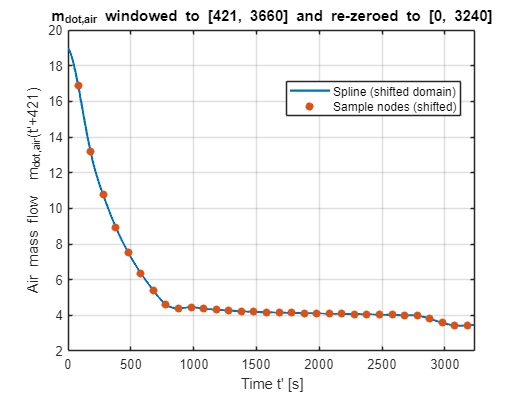

%% Plot m_dot_air(t) windowed to original [421, 3660] and re-zeroed to [0, 3240]
% Run the whole script once so MATLAB registers the local function below.

t0 = linspace(0, 3240, 2001);           % new domain
f0 = dot_m_air_0to3240(t0);

figure
plot(t0, f0, 'LineWidth', 1.6); grid on
xlabel('Time t'' [s]'); ylabel('Air mass flow  m_{dot,air}(t''+421)');
title('m_{dot,air} windowed to [421, 3660] and re-zeroed to [0, 3240]')
xlim([0 3240])

% Overlay shifted original 100-s sample nodes
tn_all   = 1:100:4500;                  % original node times (1..4401)
mask     = (tn_all >= 421) & (tn_all <= 3660);
tn_shift = tn_all(mask) - 421;          % now 0..3240
fn_shift = dot_m_air_0to3240(tn_shift);

hold on
scatter(tn_shift, fn_shift, 35, 'filled')
xline(0,'--'); xline(3240,'--');
legend('Spline (shifted domain)','Sample nodes (shifted)','Location','best')



%% Local function (keeps your data/code; evaluates at t = t' + 421, domain 0..3240)

function flow = dot_m_air_0to3240(tprime)
    % Original samples (kept as-is)
    power_values = [0.370775472872228, 4.14655917085228, 10.2236066715828, ...
                    15.9335661862365, 19.0351731908349, 16.9149763039733, ...
                    13.1623042033400, 10.7569435504486, 8.94905877526484, ...
                    7.51589529502896, 6.36393337822089, 5.39660249912924, ...
                    4.60743235399543, 4.39417963045294, 4.45647923355531, ...
                    4.36949731785185, 4.31573725145724, 4.26746478317914, ...
                    4.22732179826729, 4.19595415374334, 4.17143491891122, ...
                    4.15169555274063, 4.13523300363972, 4.12099504031059, ...
                    4.10816091872904, 4.09600581489035, 4.08381103149970, ...
                    4.07079463660703, 4.05616667450225, 4.03954164705557, ...
                    4.02160559806096, 4.00355147248531, 3.98237533346872, ...
                    3.81444977989844, 3.58043631849297, 3.43750882096772, ...
                    3.44017594340288, 3.48343898919501, 3.38952732636595, ...
                    3.08055145207970, 2.48510068273254, 1.52973911636135, ...
                    0.577892294612315, 0.0671525631123886, 1.01083847375133e-34];

    % Original time stamps (kept as-is)
    time_vector = 1:100:4500;

    % New-domain guard
    if any(tprime(:) < 0 | tprime(:) > 3240)
        error('t'' must be within 0 to 3240 seconds.');
    end

    % Interpolate with the original spline, evaluated at shifted time t = t' + 421
    spline_fit = spline(time_vector, power_values);
    flow = ppval(spline_fit, tprime + 421);
end